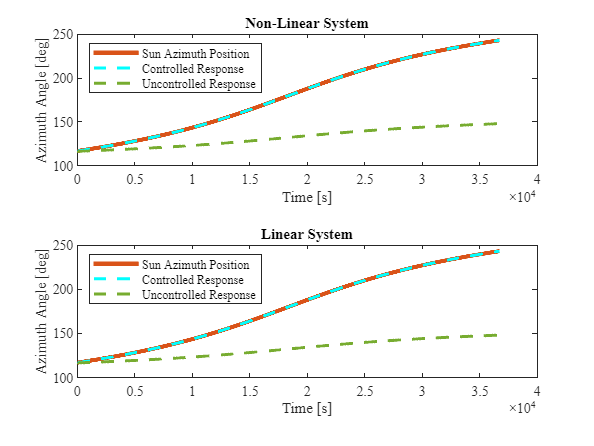

out3 = sim("Winter_Controlled.slx");
out4 = sim("Winter_Uncontrolled.slx");

Winter_Cont_data = out3.JunCont;
 
Winter_time = out3.JunCont.signals(1).values;
Winter_sundata = out3.JunCont.signals(2).values*180/pi;

Winter_Cont_nonlinear = out3.JunCont.signals(3).values*180/pi;
Winter_Cont_linear = out3.JunCont.signals(4).values*180/pi;

Winter_Uncont_data = out4.JunUncont;

Winter_Uncont_nonlinear = out4.JunUncont.signals(3).values*180/pi;
Winter_Uncont_linear = out4.JunUncont.signals(4).values*180/pi;



% plots Summer>Linear>Controller vs Uncontrolled
subplot(2,1,1);
plot(Winter_time,Winter_sundata,LineWidth=3,Color='#D95319')
hold on
plot(Winter_time,Winter_Cont_linear,LineWidth=2,LineStyle="--",Color='#00FFFF')
hold on
plot(Winter_time,Winter_Uncont_linear,LineWidth=2,LineStyle="--",Color='#77AC30')
legend('Sun Azimuth Position','Controlled Response','Uncontrolled Response','Location','northwest')
title('Non-Linear System')
xlabel({'Time [s]';''})
ylabel('Azimuth Angle [deg]')
fontname('Times New Roman',11)
hold on

% plots Summer>Non-Linear>Controller vs Uncontrolled
subplot(2,1,2);
plot(Winter_time,Winter_sundata,LineWidth=3,Color='#D95319')
hold on
plot(Winter_time,Winter_Cont_nonlinear,LineWidth=2,LineStyle="--",Color='#00FFFF')
hold on
plot(Winter_time,Winter_Uncont_nonlinear,LineWidth=2,LineStyle="--",Color='#77AC30')
legend('Sun Azimuth Position','Controlled Response','Uncontrolled Response','Location','northwest')
title('Linear System')
xlabel('Time [s]')
ylabel('Azimuth Angle [deg]')
fontname('Times New Roman',11)
hold off